## **ECHAUFFEMENT**

v = 0:0.5:3

v =          0    0.5000    1.0000    1.5000    2.0000    2.5000    3.0000


length(v)

ans = 7

v.^2

ans =          0    0.2500    1.0000    2.2500    4.0000    6.2500    9.0000


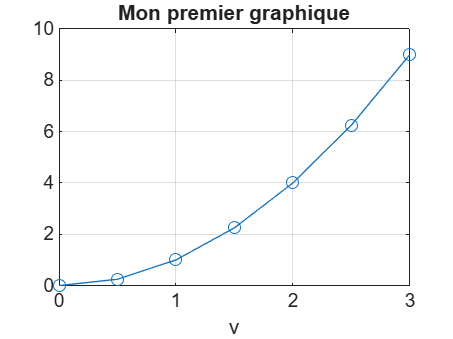

plot(v, v.^2, 'o-')
grid on
xlabel('v')
title('Mon premier graphique')

## **Q1.**** Combien d'éléments contient v = 0:0.5:3 ?**

7 éléments. 

Début:pas:fin signifie « pars de 0, avance de 0,5 en 0,5, jusqu'à 3 ». On obtient : 0 ; 0,5 ; 1 ; 1,5 ; 2 ; 2,5 ; 3.

Calcul rapide : 3 / 0,5 + 1 = 7. length(v) affiche bien 7. 

## **Q2. ****Que se passe-t-il avec v.^2 puis v^2 ? Quelle différence ?**

**v.^2** met chaque élément au carré : 0 ; 0,25 ; 1 ; 2,25 ; 4 ; 6,25 ; 9. **v^2** donne une erreur. 

Sans le point, MATLAB croit que v est une matrice et veut faire le produit matriciel v × v. 

C'est impossible pour un vecteur ligne (il faudrait une matrice carrée). À retenir :** .^ = case par case **; **^ = calcul de matrices.**

## **Q3. ****Tracez plot(v, v.^2, 'o-') puis ajoutez grille, nom d'axe et titre.**

Commandes : 

**plot(v, v.^2, 'o-'); grid on; xlabel('v'); title('Mon premier graphique');** 

On obtient une parabole qui passe par les points (0 ; 0), (1 ; 1), (2 ; 4), (3 ; 9)… Le 'o-' signifie : un rond sur chaque point (o) reliés par un trait (-).

## **PARTIE 1 - PREMIERS PAS : UNE SINUSOIDE**

%% Partie 1 — Premiers pas : une sinusoïde
fs = 8000;                     % fréquence d'échantillonnage (Hz)
t  = 0:1/fs:1-1/fs;            % vecteur temps : 1 s exactement (8000 points)
N = length(t)                  % nombre d'échantillons (fonction length)

N = 8000

f0 = 440;                      % fréquence du la (Hz)
la = sin(2*pi*f0*t)            % sinusoïde de fréquence f0

la =          0    0.3387    0.6374    0.8607    0.9823    0.9877    0.8763    0.6613    0.3681    0.0314   -0.3090   -0.6129   -0.8443   -0.9759   -0.9921   -0.8910   -0.6845   -0.3971   -0.0628    0.2790    0.5878    0.8271    0.9686    0.9956    0.9048    0.7071    0.4258    0.0941   -0.2487   -0.5621   -0.8090   -0.9603   -0.9980   -0.9178   -0.7290   -0.4540   -0.1253    0.2181    0.5358    0.7902    0.9511    0.9995    0.9298    0.7501    0.4818    0.1564   -0.1874   -0.5090   -0.7705   -0.9409


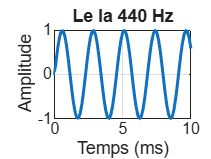

figure('Name', 'TP1_fig1_sinusoide');
plot(t*1000, la, 'LineWidth', 1.5); grid on;
xlim([0 10]);                  % zoom sur les 10 premières ms
xlabel('Temps (ms)'); ylabel('Amplitude');
title('Le la 440 Hz');

sound(la, fs);                 % écoute (1 s)
T0 = 1/f0;
fprintf('RESULTAT N = %d ; T0 = %.4f ms ; periodes dans 10 ms = %.1f\n', N, T0*1000,0.010/T0)

RESULTAT N = 8000 ; T0 = 2.2727 ms ; periodes dans 10 ms = 4.4


## **Q4. ****Combien d'échantillons contient t ? Pourquoi ce nombre ?**

8000 échantillons. On mesure 8000 fois par seconde (fs = 8000 Hz) pendant 1 seconde : 8000 × 1 = 8000. Le temps s'arrête à 1-1/fs = 0,999875 s (et non 1 s) pour ne pas compter un 8001e point. Le pas entre deux points est 1/8000 = 0,125 ms. 

## **Q5. ****Calculez la période T0 du la en ms. Combien de périodes voit-on sur 10 ms ?**

**T0 = 1/f 0 = 1/440 ≈ 0,002273 s = 2,27 ms.** 

Nombre de périodes dans 10 ms : **10 / 2,27 = 4,4**. Sur le graphique, la courbe fait 4 cycles complets.

Les sommets sont à environ 0,6 ; 2,9 ; 5,1 ; 7,4 et 9,6 ms.

## **Q6. ****Remplacez f0 = 440 par f0 = 880. Qu'entend-on ?**

On entend le même **La**, mais en **plus aigu**.

## **PARTIE 2 - L'ACCORD DE LA MAJEUR (A, C#, E)**

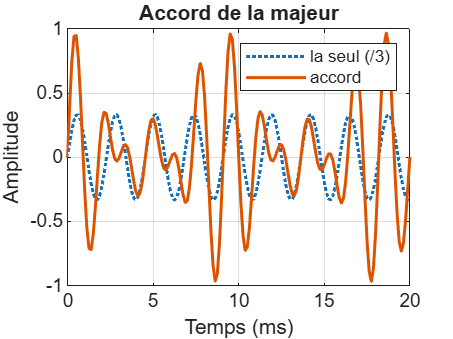

%% Partie 2 — L'accord de la majeur (A, C#, E)
dod = sin(2*pi*550*t);            %(do dièse : 550 Hz)
mi = sin(2*pi*660*t);             %(mi : 660 Hz)
accord = (la + dod + mi)/3;       %(somme normalisée des trois notes)
figure('Name', 'TP1_fig2_accord');
plot(t*1000, la/3, ':', t*1000, accord, 'LineWidth', 1.5); grid on;
xlim([0 20]); legend('la seul (/3)', 'accord');
xlabel('Temps (ms)'); ylabel('Amplitude'); title('Accord de la majeur');

sound(accord, fs);
fprintf('RESULTAT max|accord| = %.3f ; max|somme non normalisee| = %.3f\n',max(abs(accord)), max(abs(3*accord)))

RESULTAT max|accord| = 0.968 ; max|somme non normalisee| = 2.905


## **Q7. ****Pourquoi divise-t-on la somme par 3 ? Que se passerait-il sinon ?**

On divise par 3 pour que le résultat reste en -1 et 1, car tout ce qui depasse est coupé, ce qui déforme le son.

## **Q8. ****L'accord semble compliqué, mais il est périodique. En observant la figure, estimez sa période. Pouvez-vous  la retrouver par le calcul ?**

On sait que f0 = PGCD(f1,f2). Alors on a:

440 = 4*110; 550 = 5*110; 660 = 6*110

Donc PGCD(440, 550, 660) = 110

Ainsi T0 = 1/110 = 9,09ms

## **PARTIE 3 - SPECTRE DE L'ACCORD**

%% Partie 3 — Spectre de l'accord
figure('Name', 'TP1_fig3_spectre');
ts_spectre(accord, fs)

ans =      0
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10
    11
    12
    13
    14


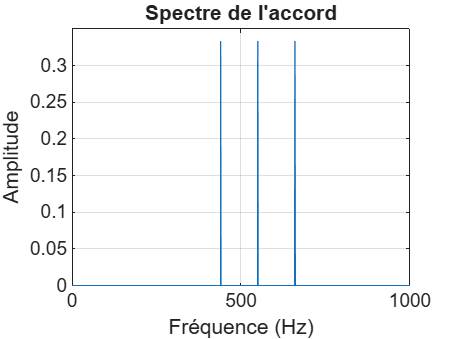

xlim([0 1000]); title('Spectre de l''accord');

[f, A] = ts_spectre(accord, fs);
[val, pos] = ts_pics(A, 0.1, 5);   % raies supérieures à 0,1
fprintf('RESULTAT raie : %6.1f Hz   amplitude %.3f\n', [f(pos)'; val']);

RESULTAT raie :  440.0 Hz   amplitude 0.333
RESULTAT raie :  550.0 Hz   amplitude 0.333
RESULTAT raie :  660.0 Hz   amplitude 0.333


## Tableau à compléter:

Note	Fréquence lue (Hz)	     Amplitude lue

la	               440,0	                0,333

do♯	               550,0	                0,333

mi	               660,0	                0,333

## **Q9. ****Pourquoi les trois raies ont-elles une hauteur de 1/3 et non de 1 ?**

Ils avaient tous une amplitude de 1 mais on a diviser par 3 pour fabriquer l'accord.

## **PARTIE 4 - EXTRAIRE LE LA AVEC UN FILTRE PASSE-BANDE**

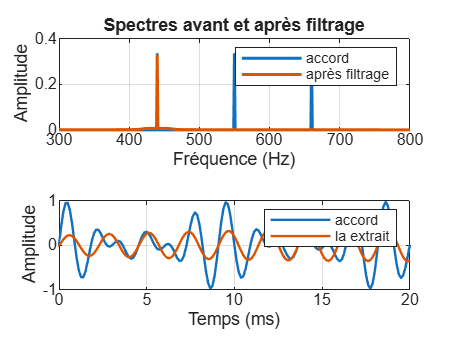

%% Partie 4 — Extraire le la avec un filtre passe-bande
[b, a] = butter(4, [420 460]/(fs/2), 'bandpass');   %(Butterworth d'ordre 4, bande 420-460 Hz)
la_extrait = filtfilt(b, a, accord);   %(filtrage sans retard de phase)
figure('Name', 'TP1_fig4_extraction');
subplot(2,1,1);
[f1, A1] = ts_spectre(accord, fs); [f2, A2] = ts_spectre(la_extrait, fs);
plot(f1, A1, f2, A2, 'LineWidth', 1.5); grid on; xlim([300 800]);
legend('accord', 'après filtrage'); xlabel('Fréquence (Hz)'); ylabel('Amplitude');
title('Spectres avant et après filtrage');
subplot(2,1,2);
plot(t*1000, accord, t*1000, la_extrait, 'LineWidth', 1.2); grid on; xlim([0 20]);
xlabel('Temps (ms)'); ylabel('Amplitude'); legend('accord', 'la extrait');

sound(la_extrait / max(abs(la_extrait)), fs);
[~, i440] = min(abs(f2 - 440)); [~, i550] = min(abs(f2 - 550));
fprintf('RESULTAT amplitude 440 Hz apres filtrage = %.3f ; amplitude 550 Hz = %.4f ;attenuation 550 Hz = %.1f dB\n', A2(i440), A2(i550), 20*log10(A2(i550)/A1(i550)))

RESULTAT amplitude 440 Hz apres filtrage = 0.327 ; amplitude 550 Hz = 0.0003 ;attenuation 550 Hz = -61.2 dB


## **Q10**. Que signifient les arguments de butter(4, [420 460]/(fs/2), 'bandpass') ?

• 4 : l'ordre du filtre. Plus il est grand, plus les bords du tamis sont raides (coupure plus nette).

 • [420 460] : les deux fréquences de coupure en Hz : on laisse passer de 420 à 460 Hz. 

• /(fs/2) : MATLAB veut des fréquences normalisées entre 0 et 1, où 1 correspond à fs/2 = 4000 Hz (la fréquence maximale que l'on peut représenter). On obtient donc 420/4000 = 0,105 et 460/4000 = 0,115. 

• 'bandpass' : le type de filtre : passe-bande (garde une bande, supprime ce qui est en dessous et au-dessus).

## **Q11.** Relevez l'atténuation du do♯ (550 Hz) en dB. Le filtrage est-il efficace. 

L'atténuation est d'environ −61 dB (votre valeur sera proche de −60 dB). Repères : −20 dB = amplitude divisée par 10 ; −40 dB = divisée par 100 ; 

−60 dB = divisée par 1000. 

Ici la raie du do♯ passe de 0,333 à environ 0,0003. 

Oui, le filtrage est très efficace : le do♯ a pratiquement disparu, alors que le la garde presque toute son amplitude (0,327 au lieu de 0,333).

## **Q12.** Remplacez la bande par [400 600]. Qu'entend-on ? Expliquez.

On entend deux notes : le la et le do♯. Le mi a presque disparu (il est atténué d'environ 28 dB). 

Explication : 440 Hz et 550 Hz sont tous les deux dans la bande 400–600 Hz, donc les deux passent. 660 Hz est en dehors, donc il est bloqué. 

Une bande plus large laisse passer plus de notes : pour isoler une seule note, la bande doit être étroite

## **Partie 5 — À vous : l'accord de do majeur (C, E, G)**

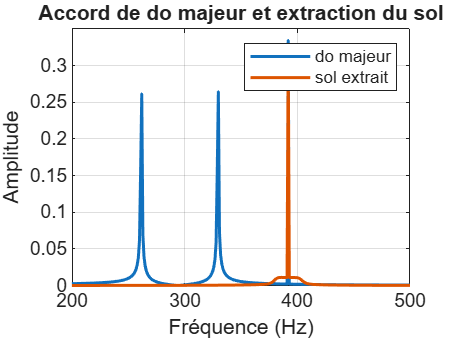

%% Partie 5 — À vous : l'accord de do majeur (C, E, G)
fdo = 261.63; fmi = 329.63; fsol = 392.00;          % 1re octave
do_maj = (sin(2*pi*fdo*t) + sin(2*pi*fmi*t) + sin(2*pi*fsol*t))/3;   %(accord de do majeur)
[b2, a2] = butter(4, [380 404]/(fs/2), 'bandpass');   %(bande autour de 392 Hz)
sol = filtfilt(b2, a2, do_maj);
figure('Name', 'TP1_fig5_do_majeur');
[f1, A1] = ts_spectre(do_maj, fs); [f2, A2] = ts_spectre(sol, fs);
plot(f1, A1, f2, A2, 'LineWidth', 1.5); grid on; xlim([200 500]);
legend('do majeur', 'sol extrait'); xlabel('Fréquence (Hz)'); ylabel('Amplitude');
title('Accord de do majeur et extraction du sol');

sound(do_maj, fs);
fprintf('RESULTAT rapports do majeur : %.3f %.3f\n', fmi/fdo, fsol/fdo)

RESULTAT rapports do majeur : 1.260 1.498


## **Q13. ****Calculez fmi /f do et f sol /f do . Comparez avec l'accord de la majeur?**

fmi /f do = 329,63 / 261,63 ≈ 1,260 ; f sol /f do = 392,00 / 261,63 ≈ 1,498. 

Pour le la majeur : 550/440 = 1,25 et 660/440 = 1,5. 

On remarque que les rapports sont (presque) les mêmes : environ 1,25 (soit 5/4) et 1,5 (soit 3/2). 

Un accord majeur a toujours la même « recette », quelle que soit la note de départ : ses fréquences sont dans les proportions 4 : 5 : 6. (Les petites différences viennent de l'accord des instruments : 1,260 = 24/12 et 1,498 = 27/12.).

## **Q14. ****Quelle bande avez-vous choisie pour le sol ? Pourquoi doit-elle être plus étroite que pour le la ?**

Bande choisie : [380 404] Hz (392 ± 12 Hz). Raison : les notes sont plus proches les unes des autres.

Le sol est à seulement 62 Hz du mi (392 − 329,63), alors que le la était à 110 Hz du do♯ (550 − 440). 

Si la bande est trop large, le mi passe aussi : avec [300 500], le mi garde une amplitude de 0,26 (presque autant que le sol, 0,33), et l'extraction rate.

## **Défi — L'accord mystère**

%% Étape 1 — Écouter et regarder
sound(x, fs);
t = (0:length(x)-1)'/fs;
figure('Name', 'TP1_defi_signal');
subplot(2,1,1); plot(t*1000, x); xlim([0 30]); grid on; xlabel('Temps (ms)'); title('Accord mystere');
subplot(2,1,2); ts_spectre(x, fs); xlim([0 1000]); title('Spectre');